% Load the necessary files
load('HCP_Contrast_FC_HCP_MMP.mat')
load('HCP_FC_HCP_MMP.mat')
load HCPex_LabelID.mat; % standard HCPex, 360 long. Huang, Rolls et al 2022 doi: 10.1007/s00429-021-02421-6
HCP_name = LabelID(:,4);
load('HCP_task_rest_covariates.mat')
load('labels_regions_2.mat')
HCP_L=HCP_name(1:180);
HCP_R=HCP_name(181:360);

% Prepare the task-related functional connectivty matrices 
% The matrices are to be stored in 360x360x100 matrcies
% or in 180x180x100 for single hemisphere data
Emotion_FC=cell2mat(HCP_FC(1).FC(:,2));
Emotion_FC=reshape(Emotion_FC,360,100,360);
Emotion_FC=permute(Emotion_FC,[1,3,2]);
Emotion_FC_L=Emotion_FC(1:180,1:180,:);
Emotion_FC_R=Emotion_FC(181:360,181:360,:);
Gambling_FC=cell2mat(HCP_FC(2).FC(:,2));
Gambling_FC=reshape(Gambling_FC,360,100,360);
Gambling_FC=permute(Gambling_FC,[1,3,2]);
Gambling_FC_L=Gambling_FC(1:180,1:180,:);
Gambling_FC_R=Gambling_FC(181:360,181:360,:);
Language_FC=cell2mat(HCP_FC(3).FC(:,2));
Language_FC=reshape(Language_FC,360,100,360);
Language_FC=permute(Language_FC,[1,3,2]);
Language_FC_L=Language_FC(1:180,1:180,:);
Language_FC_R=Language_FC(181:360,181:360,:);
Motor_FC=cell2mat(HCP_FC(4).FC(:,2));
Motor_FC=reshape(Motor_FC,360,100,360);
Motor_FC=permute(Motor_FC,[1,3,2]);
Motor_FC_L=Motor_FC(1:180,1:180,:);
Motor_FC_R=Motor_FC(181:360,181:360,:);
Relational_FC=cell2mat(HCP_FC(5).FC(:,2));
Relational_FC=reshape(Relational_FC,360,100,360);
Relational_FC=permute(Relational_FC,[1,3,2]);
Relational_FC_L=Relational_FC(1:180,1:180,:);
Relational_FC_R=Relational_FC(181:360,181:360,:);
Social_FC=cell2mat(HCP_FC(6).FC(:,2));
Social_FC=reshape(Social_FC,360,100,360);
Social_FC=permute(Social_FC,[1,3,2]);
Social_FC_L=Social_FC(1:180,1:180,:);
Social_FC_R=Social_FC(181:360,181:360,:);
WM_FC=cell2mat(HCP_FC(7).FC(:,2));
WM_FC=reshape(WM_FC,360,100,360);
WM_FC=permute(WM_FC,[1,3,2]);
WM_FC_L=WM_FC(1:180,1:180,:);
WM_FC_R=WM_FC(181:360,181:360,:);
Rest_FC=cell2mat(HCP_FC(8).FC(:,2));
Rest_FC=reshape(Rest_FC,360,100,360);
Rest_FC=permute(Rest_FC,[1,3,2]);
Rest_FC_L=Rest_FC(1:180,1:180,:);
Rest_FC_R=Rest_FC(181:360,181:360,:);

% Prepare the subtask-related functional connectivity matrices
% The matrices are to be stored in 360x360x100 matrcies
% or in 180x180x100 for single hemisphere data
Emotion_fear_FC=reshape([HCP_contrast_FC(1).FC.fear],360,360,100);
[Emotion_fear_FC_L,Emotion_fear_FC_R]=split_HS(Emotion_fear_FC);
Emotion_neut_FC=reshape([HCP_contrast_FC(1).FC.neut],360,360,100);
[Emotion_neut_FC_L,Emotion_neut_FC_R]=split_HS(Emotion_neut_FC);
Gambling_win_FC=reshape([HCP_contrast_FC(2).FC.win],360,360,100);
[Gambling_win_FC_L,Gambling_win_FC_R]=split_HS(Gambling_win_FC);
Gambling_loss_FC=reshape([HCP_contrast_FC(2).FC.loss],360,360,100);
[Gambling_loss_FC_L,Gambling_loss_FC_R]=split_HS(Gambling_loss_FC);
Language_math_FC=reshape([HCP_contrast_FC(3).FC.math],360,360,100);
[Language_math_FC_L,Language_math_FC_R]=split_HS(Language_math_FC);
Language_story_FC=reshape([HCP_contrast_FC(3).FC.story],360,360,100);
[Language_story_FC_L,Language_story_FC_R]=split_HS(Language_story_FC);
Motor_lf_FC=reshape([HCP_contrast_FC(4).FC.lf],360,360,100);
[Motor_lf_FC_L,Motor_lf_FC_R]=split_HS(Motor_lf_FC);
Motor_rf_FC=reshape([HCP_contrast_FC(4).FC.rf],360,360,100);
[Motor_rf_FC_L,Motor_rf_FC_R]=split_HS(Motor_rf_FC);
Motor_lh_FC=reshape([HCP_contrast_FC(4).FC.lh],360,360,100);
[Motor_lh_FC_L,Motor_lh_FC_R]=split_HS(Motor_lh_FC);
Motor_rh_FC=reshape([HCP_contrast_FC(4).FC.rh],360,360,100);
[Motor_rh_FC_L,Motor_rh_FC_R]=split_HS(Motor_rh_FC);
Motor_t_FC=reshape([HCP_contrast_FC(4).FC.t],360,360,100);
[Motor_t_FC_L,Motor_t_FC_R]=split_HS(Motor_t_FC);
Relational_match_FC=reshape([HCP_contrast_FC(5).FC.match],360,360,100);
[Relational_match_FC_L,Relational_match_FC_R]=split_HS(Relational_match_FC);
Relational_relation_FC=reshape([HCP_contrast_FC(5).FC.relation],360,360,100);
[Relational_relation_FC_L,Relational_relation_FC_R]=split_HS(Relational_relation_FC);
Rest_FC=reshape([HCP_contrast_FC(6).FC.Rest],360,360,100);
[Rest_FC_L,Rest_FC_R]=split_HS(Rest_FC);
Social_mental_FC=reshape([HCP_contrast_FC(7).FC.mental],360,360,100);
[Social_mental_FC_L,Social_mental_FC_R]=split_HS(Social_mental_FC);
Social_rnd_FC=reshape([HCP_contrast_FC(7).FC.rnd],360,360,100);
[Social_rnd_FC_L,Social_rnd_FC_R]=split_HS(Social_rnd_FC);
WM_body_FC=reshape([HCP_contrast_FC(8).FC.f0bk_body],360,360,100);
[WM_body_FC_L,WM_body_FC_R]=split_HS(WM_body_FC);
WM_faces_FC=reshape([HCP_contrast_FC(8).FC.f0bk_faces],360,360,100);
[WM_faces_FC_L,WM_faces_FC_R]=split_HS(WM_faces_FC);
WM_places_FC=reshape([HCP_contrast_FC(8).FC.f0bk_places],360,360,100);
[WM_places_FC_L,WM_places_FC_R]=split_HS(WM_places_FC);
WM_tools_FC=reshape([HCP_contrast_FC(8).FC.f0bk_tools],360,360,100);
[WM_tools_FC_L,WM_tools_FC_R]=split_HS(WM_tools_FC);

% Obtain task mean 
Mean_FC=(Emotion_FC+Gambling_FC+Language_FC+Motor_FC+Relational_FC+Social_FC+WM_FC+Rest_FC)./8;
[Mean_FC_L,Mean_FC_R]=split_HS(Mean_FC);

% Calculate the mean FC across the subtasks of each tasks 
Emotion_mean_FC=(Emotion_neut_FC+Emotion_fear_FC)./2;
[Emotion_mean_FC_L,Emotion_mean_FC_R]=split_HS(Emotion_mean_FC);
Gambling_mean_FC=(Gambling_win_FC+Gambling_loss_FC)./2;
[Gambling_mean_FC_L,Gambling_mean_FC_R]=split_HS(Gambling_mean_FC);
Language_mean_FC=(Language_math_FC+Language_story_FC)./2;
[Language_mean_FC_L,Language_mean_FC_R]=split_HS(Language_mean_FC);
Motor_mean_FC=(Motor_t_FC+Motor_rh_FC+Motor_lh_FC+Motor_lf_FC+Motor_rf_FC)./5;
[Motor_mean_FC_L,Motor_mean_FC_R]=split_HS(Motor_mean_FC);
Relational_mean_FC=(Relational_relation_FC+Relational_match_FC)./2;
[Relational_mean_FC_L,Relational_mean_FC_R]=split_HS(Relational_mean_FC);
Social_mean_FC=(Social_rnd_FC+Social_mental_FC)./2;
[Social_mean_FC_L,Social_mean_FC_R]=split_HS(Social_mean_FC);
WM_mean_FC=(WM_tools_FC+WM_places_FC+WM_faces_FC+WM_body_FC)./4;
[WM_mean_FC_L,WM_mean_FC_R]=split_HS(WM_mean_FC);

% Obtain subtask mean
Mean_FC_2=(Emotion_mean_FC+Gambling_mean_FC+Language_mean_FC+Motor_mean_FC+Relational_mean_FC+Social_mean_FC+WM_mean_FC+Rest_FC_2)./8;
[Mean_FC_2_L,Mean_FC_2_R]=split_HS(Mean_FC_2);

% Vectorize the full functional connectivity matrices
Emotion_FC_flat=flatten(Emotion_FC);
Gambling_FC_flat=flatten(Gambling_FC);
Language_FC_flat=flatten(Language_FC);
Motor_FC_flat=flatten(Motor_FC);
Relational_FC_flat=flatten(Relational_FC);
Social_FC_flat=flatten(Social_FC);
Rest_FC_flat=flatten(Rest_FC);
WM_FC_flat=flatten(WM_FC);

% Split each task's data into training and test sets (80% for training, 20% for testing)
[Emotion_train,Emotion_test]=split_train_test(Emotion_FC_flat,0.8,11);
[Gambling_train,Gambling_test]=split_train_test(Gambling_FC_flat,0.8,12);
[Language_train,Language_test]=split_train_test(Language_FC_flat,0.8,13);
[Motor_train,Motor_test]=split_train_test(Motor_FC_flat,0.8,14);
[Relational_train,Relational_test]=split_train_test(Relational_FC_flat,0.8,15);
[Social_train,Social_test]=split_train_test(Social_FC_flat,0.8,16);
[Rest_train,Rest_test]=split_train_test(Rest_FC_flat,0.8,17);
[WM_train,WM_test]=split_train_test(WM_FC_flat,0.8,18);

% Combine training datasets from different tasks
train_input=[Emotion_train;
    Gambling_train;
    Language_train;
    Motor_train;
    Relational_train;
    Social_train;
    Rest_train;
    WM_train];

% Combine test datasets from different tasks
test_input=[Emotion_test;
    Gambling_test;
    Language_test;
    Motor_test;
    Relational_test;
    Social_test;
    Rest_test;
    WM_test];


% Create numerical labels for the training set (1 for Emotion, 2 for Gambling, and so on)
train_outputs_num = [ones(80,1);
                     2*ones(80,1);
                     3*ones(80,1);
                     4*ones(80,1);
                     5*ones(80,1);
                     6*ones(80,1);
                     7*ones(80,1);
                     8*ones(80,1);];

% Create numerical labels for the test set (1 for Emotion, 2 for Gambling, and so on)
test_outputs_num = [ones(20,1);
                    2*ones(20,1);
                    3*ones(20,1);
                    4*ones(20,1);
                    5*ones(20,1);
                    6*ones(20,1);
                    7*ones(20,1);
                    8*ones(20,1);];

% Convert numerical labels to task names
tasks = ["Emotion", "Gambling", "Language", "Motor", "Relational", "Social", "Rest", "WM"];
train_outputs = tasks(train_outputs_num)';
test_outputs = tasks(test_outputs_num)';

% Assigning input and output variables for training and test sets
X_train=train_input;
Y_train=train_outputs;
X_test=test_input;
Y_test=test_outputs;

% Set random seed for reproducibility
rng(10);

% 1. Training-validation split
cv = cvpartition(Y_train, 'KFold', 4);

% Preallocate storage
standardization_storage = cell(1, cv.NumTestSets);

% 2. For each fold in the cross-validation:
for i1 = 1:cv.NumTestSets
    train_idx = cv.training(i1);
    val_idx = cv.test(i1);

    % 2(a) Standardization of training data subset for each fold
    mu_train = mean(X_train(train_idx, :));
    sigma_train = std(X_train(train_idx, :));
    X_train_standardized = (X_train(train_idx, :) - mu_train) ./ sigma_train;

    % 2(b) Standardization of validation data subset for each fold
    X_val_standardized = (X_train(val_idx, :) - mu_train) ./ sigma_train;

    % 2(c) Storing standardized data
    standardization_storage{i1} = {X_train_standardized, X_val_standardized};
end


% Preallocate storage
pca_storage = cell(1, cv.NumTestSets);

% 1. For each fold in the cross-validation:
for i1 = 1:cv.NumTestSets
    train_idx = cv.training(i1);
    val_idx = cv.test(i1);

    % 1(a) Retrieving the standardized data from each fold
    data = standardization_storage{i1};
    X_train_standardized = data{1};

    % 1(b) PCA on standardized training data for each fold
    [coeff, score, latent] = pca(X_train_standardized);

    % 1(c) Storing PCA results for each fold
    pca_storage{i1} = {coeff, score, latent};
end



% Set random seed for reproducibility
rng(10);

% Choice of model: one vs all or one vs one
%coding = 'onevsone';
coding = 'onevsall';

% 1. Hyperparameter setting
c_range = [0.00001, 0.00002, 0.00003, 0.00004, 0.00007, 0.0001, 0.0003, 0.001, 0.01, 0.1, 1]; 

% 2. Setting the desired explained variance
explained_var_range = [0.5, 0.8, 0.9, 0.95, 0.99, 0.99999];

% Preallocate a matrix for validation accuracies
val_accuracies = zeros(length(explained_var_range), length(c_range));

% Initialization for the best parameters search
min_loss = Inf;
best_c = 0;
best_var = 0;

% 3. For each explained variance value
for var_idx = 1:length(explained_var_range)
    desired_var = explained_var_range(var_idx);

    % 3(a). For each hyperparameter 'C' value
    for c_idx = 1:length(c_range)
        c = c_range(c_idx);
        cum_loss = 0;
        temp_acc = 0;  % Accuracy accumulator for the folds

        % 3(a)(i). For each fold
        for i1 = 1:cv.NumTestSets
            % 3(a)(i)(A). Retrieving the data from each fold
            standardization_data = standardization_storage{i1};
            X_train_standardized = standardization_data{1};
            X_val_standardized = standardization_data{2};
            pca_data = pca_storage{i1};
            coeff = pca_data{1};
            score = pca_data{2};
            latent = pca_data{3};

            % 3(a)(i)(B). Retaining the principal components
            explained = cumsum(latent) / sum(latent);
            num_PCs = find(explained >= desired_var, 1);
            X_train_reduced = score(:, 1:num_PCs);

            % 3(a)(i)(C). Projection onto the principal components for each fold
            X_val_reduced = X_val_standardized * coeff(:, 1:num_PCs);

            % 3(a)(i)(D). Model training and validation
            svm = templateSVM('BoxConstraint', c, 'KernelFunction', 'linear');
            SVMModel = fitcecoc(X_train_reduced, Y_train(cv.training(i1)), 'Learners', svm, 'Coding', coding);
            predictions = predict(SVMModel, X_val_reduced);
            fold_loss = sum(predictions ~= Y_train(cv.test(i1)));
            cum_loss = cum_loss + fold_loss;
            temp_acc = temp_acc + (1 - fold_loss/length(predictions));
        end

        % 3(a)(ii). Calculate cumulative validation loss across all folds
        val_accuracies(var_idx, c_idx) = temp_acc / cv.NumTestSets;

        % Display validation results
        fprintf('Explained Variance = %.2f, C = %f: Validation Accuracy = %.2f%%\n', explained_var_range(var_idx), c_range(c_idx), val_accuracies(var_idx, c_idx)*100);

        % Model selection based on cumulative loss
        if cum_loss < min_loss
            min_loss = cum_loss;
            best_c = c;
            best_var = desired_var;
        end
    end
end

Explained Variance = 0.50, C = 0.000010: Validation Accuracy = 81.41%
Explained Variance = 0.50, C = 0.000020: Validation Accuracy = 84.53%
Explained Variance = 0.50, C = 0.000030: Validation Accuracy = 86.09%
Explained Variance = 0.50, C = 0.000040: Validation Accuracy = 86.56%
Explained Variance = 0.50, C = 0.000070: Validation Accuracy = 86.88%
Explained Variance = 0.50, C = 0.000100: Validation Accuracy = 86.41%
Explained Variance = 0.50, C = 0.000300: Validation Accuracy = 84.69%
Explained Variance = 0.50, C = 0.001000: Validation Accuracy = 83.91%
Explained Variance = 0.50, C = 0.010000: Validation Accuracy = 80.00%
Explained Variance = 0.50, C = 0.100000: Validation Accuracy = 77.19%
Explained Variance = 0.50, C = 1.000000: Validation Accuracy = 76.56%
Explained Variance = 0.80, C = 0.000010: Validation Accuracy = 87.34%
Explained Variance = 0.80, C = 0.000020: Validation Accuracy = 88.75%
Explained Variance = 0.80, C = 0.000030: Validation Accuracy = 89.22%
Explained Variance =


% 5. Standardization of full training data
mu_train_full = mean(X_train);
sigma_train_full = std(X_train);
X_train_standardized_full = (X_train - mu_train_full) ./ sigma_train_full;

% 6. Principal component analysis
[coeff_full, score_full, latent_full] = pca(X_train_standardized_full);

% 7. Retaining the principal components
explained_full = cumsum(latent_full) / sum(latent_full);
num_PCs_full = find(explained_full >= best_var, 1);
X_train_reduced_full = score_full(:, 1:num_PCs_full);

% 8. Standardization of test data
X_test_standardized = (X_test - mu_train_full) ./ sigma_train_full;

% 9. Projection onto the principal components
X_test_reduced = X_test_standardized * coeff_full(:, 1:num_PCs_full);

% 10. Model training with the best hyperparameter and explained variance
svm_final = templateSVM('BoxConstraint', best_c, 'KernelFunction', 'linear');
SVMModelFinal = fitcecoc(X_train_reduced_full, Y_train, 'Learners', svm_final, 'Coding', coding);

% 11. Model testing
predictions_test = predict(SVMModelFinal, X_test_reduced);

% 12. Model evaluation
accuracy = sum(predictions_test == Y_test) / length(Y_test);
fprintf('Model Accuracy on Test Set: %.2f%%\n', accuracy*100);

Model Accuracy on Test Set: 91.88%


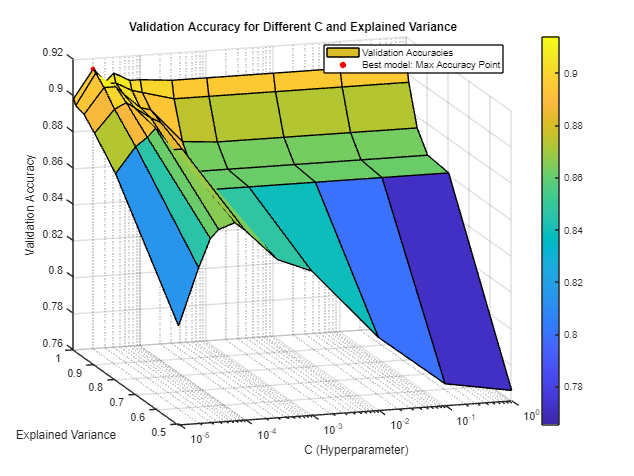

% Create a 3D plot

[X, Y] = meshgrid(c_range, explained_var_range);  % Create a meshgrid for C values and Explained Variance 

Z = val_accuracies;

figure('Position', [100, 100, 1200, 900]);
h_surf = surf(X, Y, Z);
view(-17.5, 15);
xlabel('C (Hyperparameter)');
ylabel('Explained Variance');
zlabel('Validation Accuracy');
title('Validation Accuracy for Different C and Explained Variance');
colorbar;
set(gca, 'XScale', 'log');  % Use a logarithmic scale for C as its values span several orders of magnitude

% Highlight the point of maximum accuracy in 3D space
[max_val, max_idx] = max(Z(:));
[max_row, max_col] = ind2sub(size(Z), max_idx);
hold on;
h_scatter = scatter3(X(max_row, max_col), Y(max_row, max_col), max_val, 20, 'r', 'filled');
hold off;

legend([h_surf, h_scatter], {'Validation Accuracies', 'Best model: Max Accuracy Point'}, 'Location', 'northeast');


outputFilename='svm_OvA_pca_validation';
saveas(gcf, outputFilename, 'jpg');

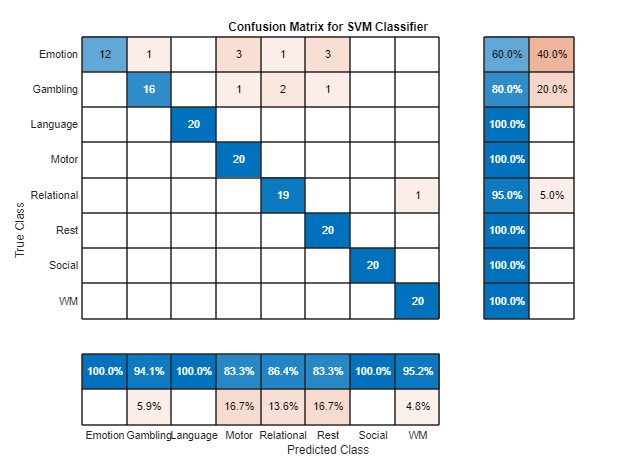

% Compute confusion matrix
[C, order] = confusionmat(Y_test, predictions_test);

% Visualize the confusion matrix using a confusion chart
confChart = confusionchart(C, order);
confChart.Title = 'Confusion Matrix for SVM Classifier';
confChart.RowSummary = 'row-normalized';  % Normalizes the count of each row
confChart.ColumnSummary = 'column-normalized';  % Normalizes the count of each column

saveas(confChart, 'SVM_linear_OvA_pca_test_confusion.jpg');

T = array2table(C, 'VariableNames', order, 'RowNames', order);